Pvc = 0.8;
Pcg = 0.35; 
Pcm = 0.05;
Pgm = 0.95;
Pmu = 0.05;

M = [1-Pvc 0 0 0 0; Pvc 1-Pcg-Pcm 0 0 0; 
    0 Pcg 1-Pgm 0 0; 0 Pcm Pgm 1-Pmu 0; 0 0 0 Pmu 1]

M =           0.2            0            0            0            0
          0.8          0.6            0            0            0
            0         0.35         0.05            0            0
            0         0.05         0.95         0.95            0
            0            0            0         0.05            1


n = [8000000; 100000; 1000; 5000; 250000] 

n =      8000000
      100000
        1000
        5000
      250000


% number of imigrant inicial (Venezuela, Colombia, Guatemala, Mexico, US)

H = [n];
T = [0];
for i=1:10
    nt = M*n;
    n = nt;
    H = [H nt];
    T = [T i];
end
format shortG;
H

H =         8e+06      1.6e+06      3.2e+05        64000        12800         2560          512        102.4        20.48        4.096       0.8192
        1e+05     6.46e+06    5.156e+06   3.3496e+06    2.061e+06   1.2468e+06   7.5014e+05   4.5049e+05   2.7038e+05   1.6224e+05        97349
         1000        35050   2.2628e+06   1.9177e+06   1.2682e+06   7.8475e+05   4.7562e+05   2.8633e+05   1.7199e+05   1.0323e+05        61947
         5000        10700   3.6646e+05   2.7556e+06   4.6071e+06   5.6846e+06   6.2083e+06   6.3872e+06   6.3624e+06   6.2212e+06   6.0163e+06
      2.5e+05   2.5025e+05   2.5078e+05   2.6911e+05   4.0689e+05   6.3724e+05   9.2147e+05   1.2319e+06   1.5512e+06   1.8694e+06   2.1804e+06


T

T =      0     1     2     3     4     5     6     7     8     9    10


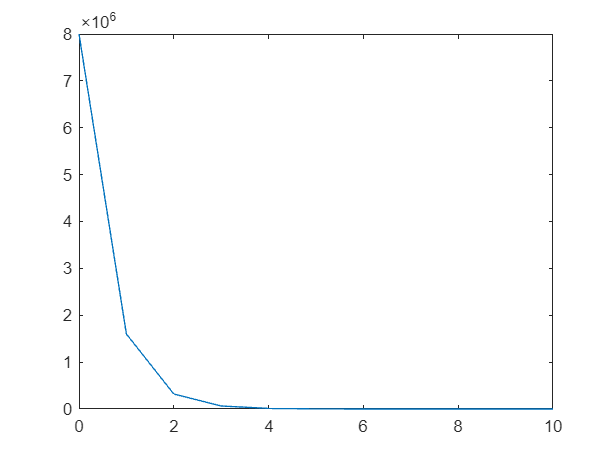

plot(T,H(1,:))

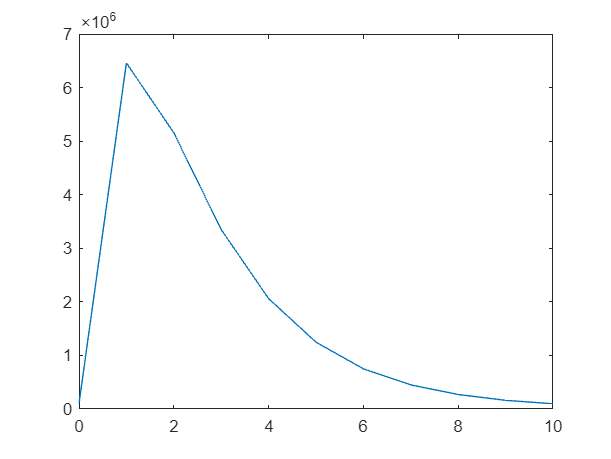

plot(T,H(2,:))

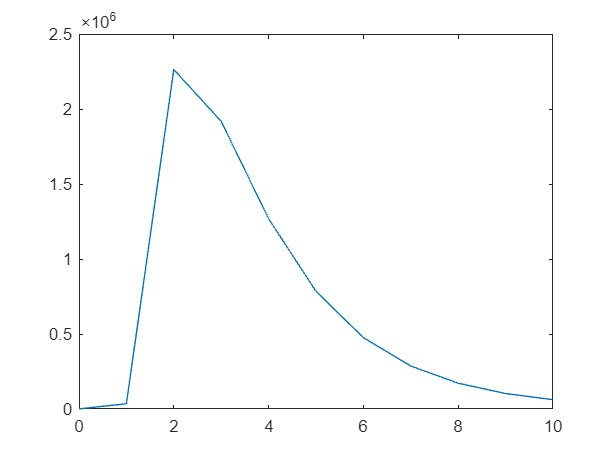

plot(T,H(3,:))

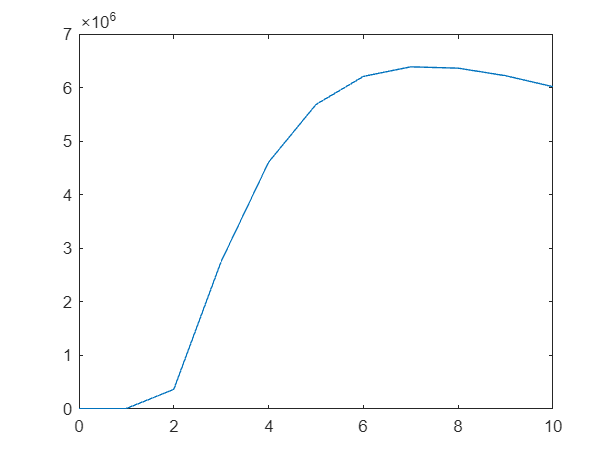

plot(T,H(4,:))

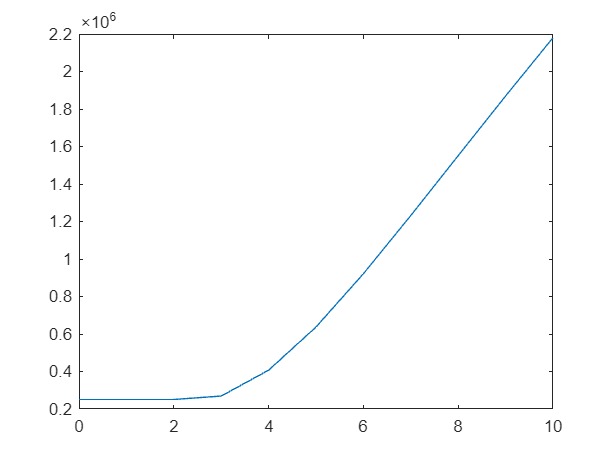

plot(T,H(5,:))